Optimalfall:

TP3

[Ziel_Coeff_Za_TP3,Ziel_Coeff_Ne_TP3] = cheby1(3,3,368000,'low', 's');  %58.569kHz
Ziel_Coeff_Ne_TP3 = Ziel_Coeff_Ne_TP3 / Ziel_Coeff_Za_TP3(4);  % (4) zur sicherheit, wegen Format
Ziel_Coeff_Za_TP3 = Ziel_Coeff_Za_TP3 / Ziel_Coeff_Za_TP3(4);

f_von_p_TP3 = tf(Ziel_Coeff_Za_TP3,Ziel_Coeff_Ne_TP3)

BodeDgrTP3 = bodeplot(f_von_p_TP3); 

f_von_p_TP3 =
 
                        1
  ----------------------------------------------
  8.007e-17 s^3 + 1.76e-11 s^2 + 1.007e-05 s + 1
 
Continuous-time transfer function.



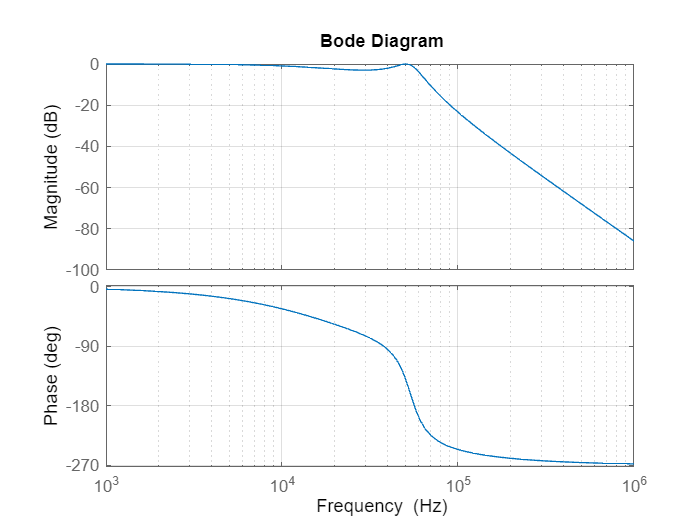

opt = getoptions(BodeDgrTP3);
opt.Grid = 'on';
opt.FreqUnits = 'Hz';
setoptions(BodeDgrTP3,opt);

step(f_von_p_TP3); %Einschaltverhalten

HP3

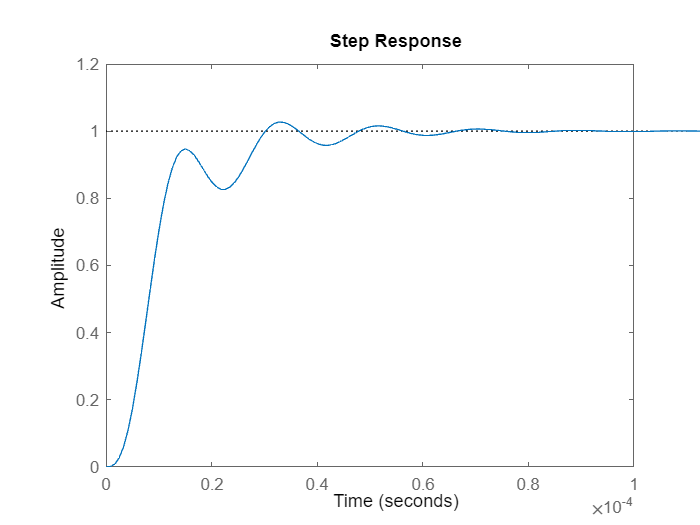

[Ziel_Coeff_Zae_HP3, Ziel_Coeff_Ne_HP3] = cheby1(3,3,270177,'high', 's');   %43kHZ

Ziel_Coeff_Zae_HP3 = Ziel_Coeff_Zae_HP3 / Ziel_Coeff_Ne_HP3(4);
Ziel_Coeff_Ne_HP3 = Ziel_Coeff_Ne_HP3 / Ziel_Coeff_Ne_HP3(4);
f_von_p_HP3 = tf(Ziel_Coeff_Zae_HP3,Ziel_Coeff_Ne_HP3)

BodeDgr1HP3 = bodeplot(f_von_p_HP3); 
opt = getoptions(BodeDgr1HP3);

f_von_p_HP3 =
 
                   1.271e-17 s^3
  -----------------------------------------------
  1.271e-17 s^3 + 1.272e-11 s^2 + 2.211e-06 s + 1
 
Continuous-time transfer function.



opt.Grid = 'on';
opt.FreqUnits = 'Hz';
setoptions(BodeDgr1HP3,opt);

step(f_von_p_HP3); %Einschaltverhalten

Bode TP*HP

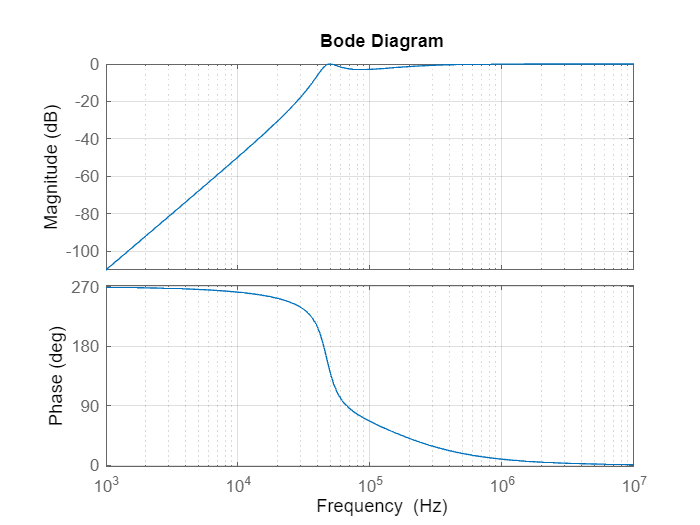

BP = f_von_p_TP3*f_von_p_HP3

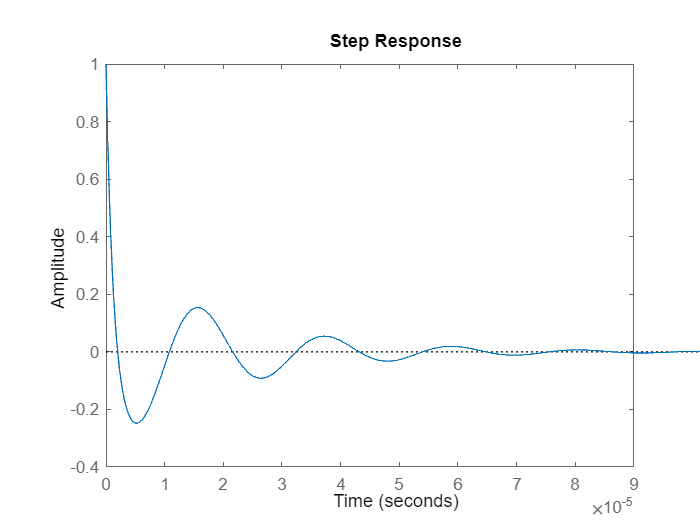

BodeDgrBP = bodeplot(BP);
opt = getoptions(BodeDgrBP);

opt.Grid = 'on';
opt.FreqUnits = 'Hz';
setoptions(BodeDgrBP,opt);

BP =
 
                                                      
                                         1.271e-17 s^3
                                                      
  --------------------------------------------------------------------------------------------
                                                                                              
  1.017e-33 s^6 + 1.242e-27 s^5 + 5.287e-22 s^4 + 2.597e-16 s^3 + 5.257e-11 s^2 + 1.228e-05 s 
                                                                                              
                                                                                           + 1
                                                                                              
 
Continuous-time transfer function.



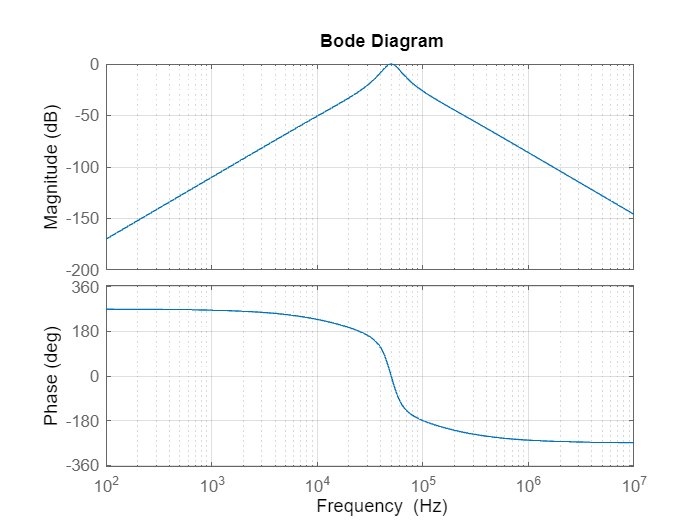

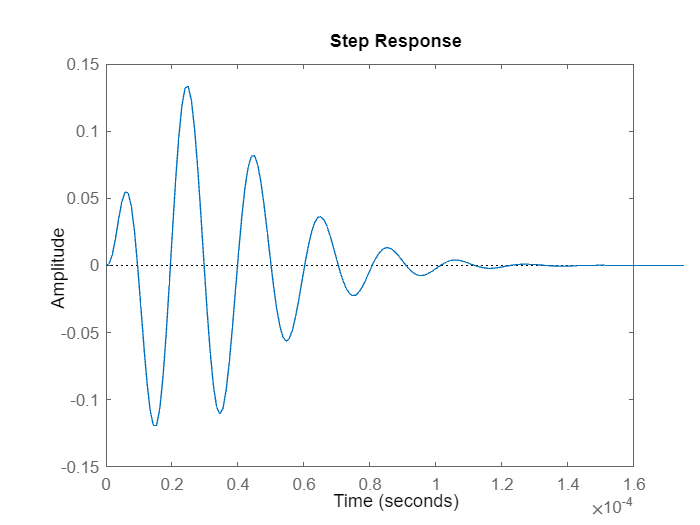

step(BP);